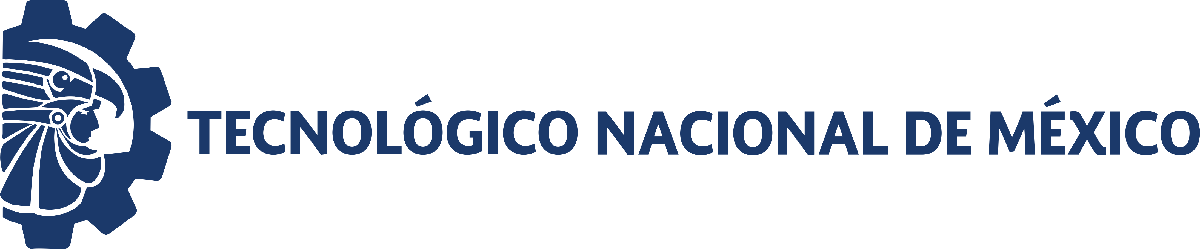                                 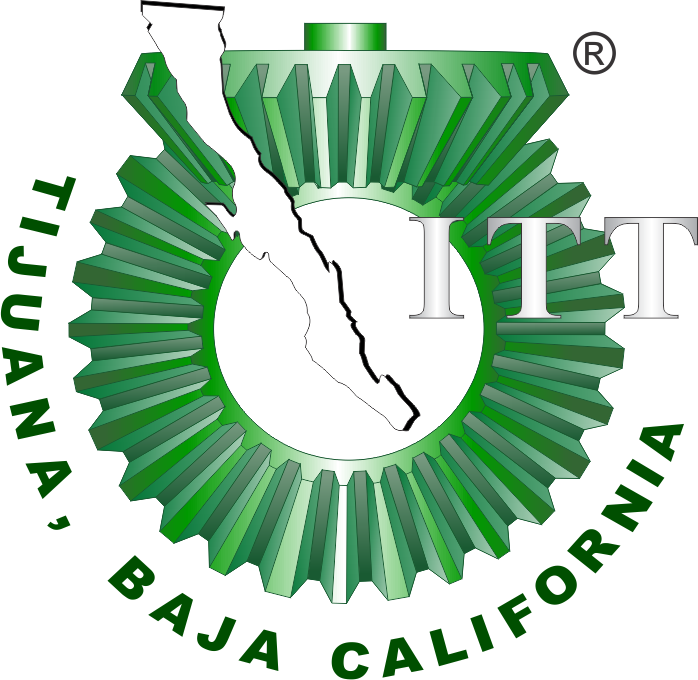

# Práctica cuatro: Modelado y control del sistema endócrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

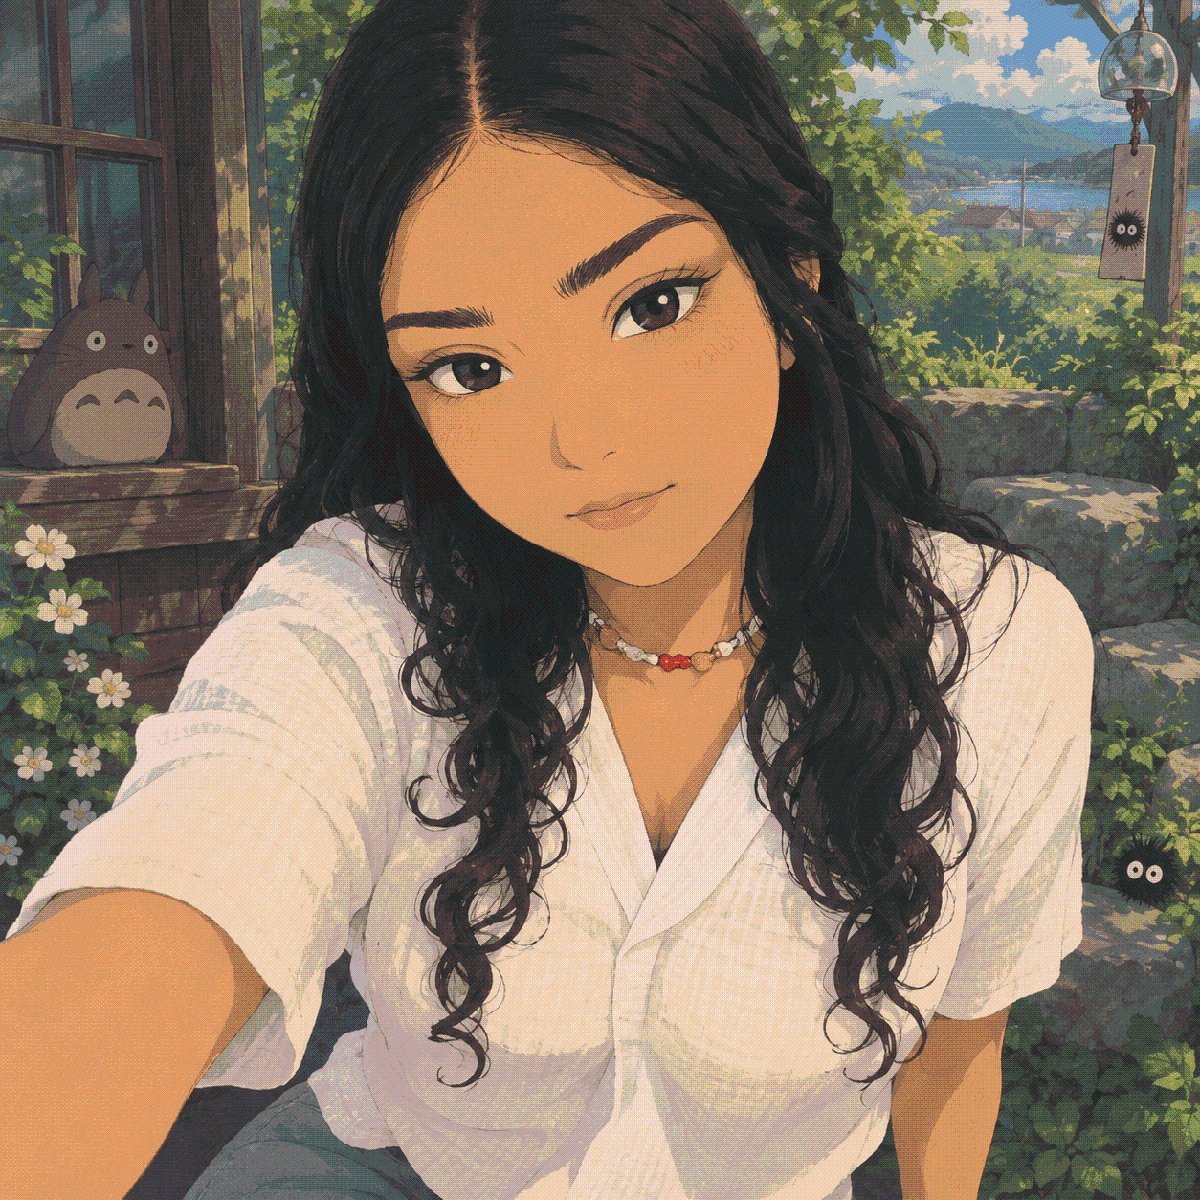

Nombre del alumno: **Zulema Guadalupe Tirado Manzo**

Número de control: **23210724**

Correo institucional: **l23210724@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')

open_system('Sistema.slx')

parameters.StopTime = '10';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-3';
x = sim('Sistema', parameters);

## **Respuesta al impulso: Control y caso**

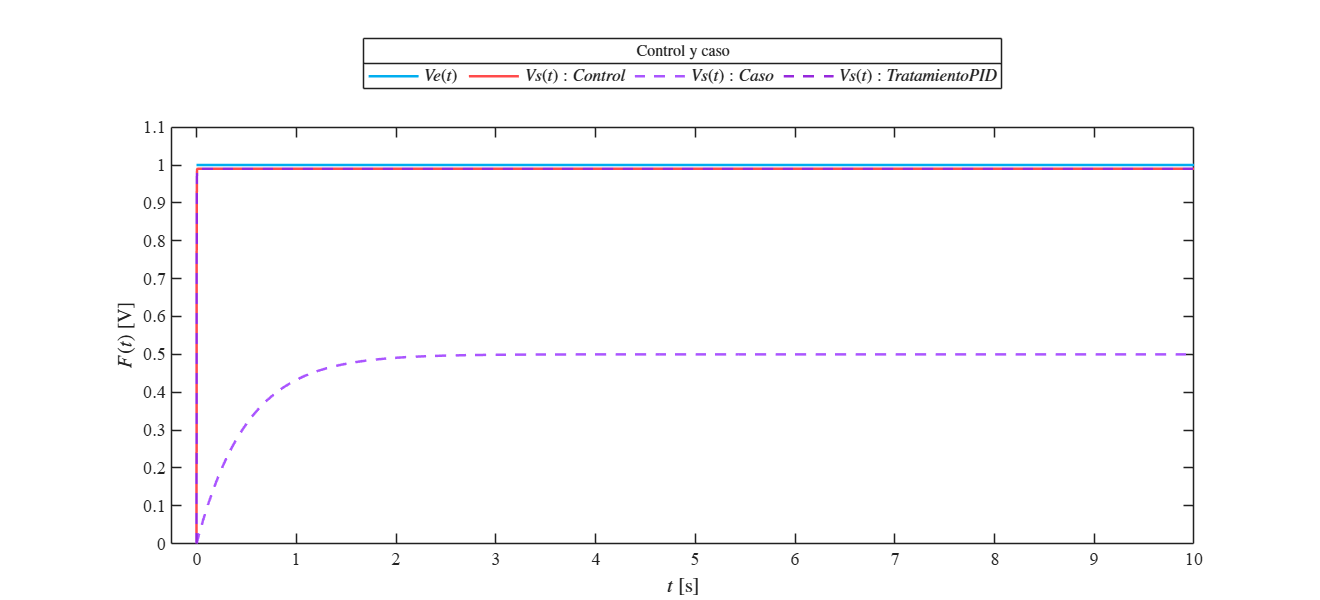

plotsignals(x.t,x.Ve,x.Vsx,x.Vsy,x.VsPID)

## Función: Respuestas de la simulación 

function plotsignals(t,c,c1,c2,c3)

set(figure(),'color','w')
set(gcf,'units','inches','position',[1,1,11,5])
set(gca,'fontname','times new roman','fontsize',11)

hold on;
grid off;
box on;

clr1 = [0, 174, 239]/255;
clr2 = [255, 75, 75]/255;
clr3 = [170, 85, 255]/255;
clr4 = [150, 40, 220]/255;

order = [clr1;clr2;clr3;clr4]; colororder(order)

plot(t,c,'-',t,c1,'-',t,c2,'--',t,c3,'--','LineWidth',1.5,'MarkerSize',5,'MarkerIndices',1:1e3:length(t));

L = legend('$Ve(t)$', '$Vs(t): Control$','$Vs(t): Caso$', '$Vs(t): Tratamiento PID$');

set(L,'interpreter','latex', 'location','northoutside', 'orientation','horizontal')

title(L,'Control y caso')

xlabel('$t$ [s]','interpreter','latex')
ylabel('$F(t)$ [V]','interpreter','latex')

xlim([-0.25 10]);
xticks(0:1:10)

ylim([0 1.1]);
yticks(0:0.1:1.1)

exportgraphics(gcf,'Control_caso_matlab.pdf','contenttype','vector')

end